# Simulation-based investigation of evolutionary stability of extortionate zero-determinant strategies

*Christoph Siebenbrunner*

*Term Project - DPhil Mathematics Broadening Requirement*

*Computational Game Theory (MT 2016)*

## Abstract

Zero-determinant (ZD) strategies are a highly interesting, recently discovered class of strategies for the iterated prisoner's dilemma and similar 2-player games. A particularly interesting variety of such ZD strategies allows one player to set its own score to a multiplicative factor of her opponent's score. If this factor is chosen to be greater than one, such strategies are called extortionate strategies and will outcompete any opponent in direct competition. While such strategies are obviously superior in any two-person player game, they perform less stellar in evolutionary settings because they performing poorly when playing against their own kind. In this project I use simulations to investigate how extortionate ZD strategies perform in evolutionary competition against different opponents, i.e. AllC-, AllD-, Tit-for-Tat, Random and Pavlov strategies. The simulation results confirm theoretical predictions and highlight some interesting stylized facts. Extortionate ZD strategies perform poorly against all opponents but manage to maintain a strictly positive population share against at least some strategies (AllC, AllD and Random). The paper discusses the simulation outcome against all strategies in detail and concludes with several avenues for further investigation.

## Introduction

Press and Dyson (2012) introduced a new class of strategies for the iterated prisoner's dilemma (IPD) as well as for other types of similar two-player games. In their seminal article the authors make at least three discoveries about the IPD:

- There exists a class of (zero-determinant, ZD) strategies which allow any player to unilaterally enforce a linear relationship between the two player's payoffs in the stationary state. This allows i.a. for one player to demand an extortionate share of payoffs in the game.

- For any two strategies with different memory size, there exists an equivalent simpler version of the longer-memory strategy with the same memory size as the shorter memory strategy.

- The nature of the IPD game changes fundamentally as soon as at least one player has knowledge of ZD strategies. In the case where e.g. one player has knowledge about ZD strategies and demands and extortionate share, and the other player has at least a Theory of Mind of its opponent, the IPD is reduced to an ultimatum game.

While the article by Press and Dyson (2012) only deals with the case of one-round memory strategy, (2) implies that their findings indeed hold for IPD games in general. As mentioned in (3), knowledge of ZD strategies fundamentally changes the nature of the IPD game.

Regarding the major contribution (1), Press and Dyson (2012) show that it is possible for one player to unilaterally enforce a linear relation between their two respective payoffs $s_x ,s_y$ in the stationary stationary only by setting his own strategy vector $p$ independent of the other players strategy:


$$\alpha s_x +\beta s_y +\gamma =0$$


This gives the player at least two possibilities: he can set his opponent's score to a fixed value, or he can set his own score to be multiplicative factor of his opponent's score (setting his own score is not possible, as shown by Press and Dyson (2012)). The latter approach is particularly interesting, as it is possible to set this factor to a value $>1$ and thus demand and extortionate share. This is achieved by solving the following system of equations:


$$p'=\Phi \left(S_x −P−\chi \left(S_y −P\right)\right)$$


Where $p'=\left(p_1 −1,p_{2\text{ }} −2,p_3 ,p_4 \right)$ contains the probabilities constituting player X's strategy, $S_x =\left(R,S,T,P\right)$ and $S_y =\left(R,T,S,P\right)$ are the payoff vectors for the two players and $\chi \text{ }$ governs the extortion factor through (Hilbe et al. 2013):


$$s_x =\chi \text{ }\left(s_y −P\right)+P$$


The above equations give formulae as a function of $\Phi \text{ }$ and $\chi \text{ }$for player X's probabilities as well as an upper bound for $\Phi \text{ }$ as a function of $\chi \text{ }$. Furthermore $\Phi >0$ and $\chi \text{ }\ge 1$. The well-known Tit-for-Tat-strategy can thus be seen to be a corner solution of a ZD strategy with $\chi =1$ and $\Phi$ taking its maximum allowed value 0.2 (Press and Dyson 2012).

## Demonstration

Press and Dyson (2012) show that when one player plays a ZD strategy then the payoff for both players is maximized if the other player chooses to cooperate unconditionally. Using the standard IPD payoffs $\left(R,S,T,P\right)=\left(3,0,5,1\right)$ the maximum expected payoffs for the two players are:


$$s_x =\frac{2+13\chi \text{ }}{2+3\chi \text{ }}$$
    
$$s_y =\frac{12+3\chi \text{ }}{2+3\chi \text{ }}$$


Looking at an IPD simulation of a ZD against a cooperative strategy that the ZD player is indeed able to demand an extortionate share of payoffs:

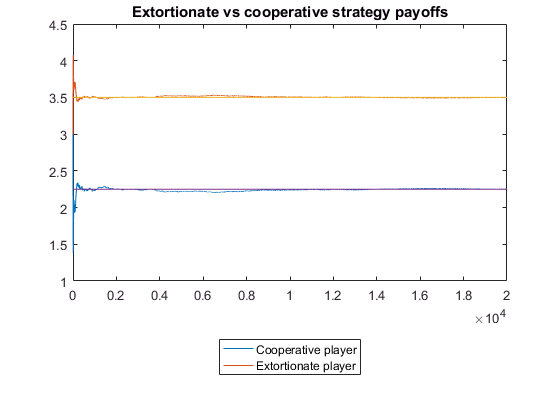

Phi = 0.1;
chi = 2;
NRounds = 20000;
PDGame = Game([3 0;5 1]);
ExtPlayer = PlayerExtortionate(Phi,chi);
AllCPlayer = PlayerAllC;
[ExtPlayer,AllCPlayer] = PDGame.playNRounds(NRounds,ExtPlayer,AllCPlayer);
figure
plot([AllCPlayer.AveragePayoffHistory ExtPlayer.AveragePayoffHistory])
title('Extortionate vs cooperative strategy payoffs')
legend({'Cooperative player' 'Extortionate player'},'Location','southoutside')
hold on
plot([0 NRounds],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
plot([0 NRounds],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])

We also see that the payoffs for both players converge to their theoretically predicted values:

disp({...
    'Payoff per strategy' 'Extortion' 'Cooperation' 'Ratio';
    'Simulation result:' ...
    ExtPlayer.AveragePayoff AllCPlayer.AveragePayoff ...
    ExtPlayer.AveragePayoff/AllCPlayer.AveragePayoff;
    'Theoretical prediction:' ...
    (2+chi*13)/(2+chi*3) (12+3*chi)/(2+3*chi) ...
    ((2+chi*13)/(2+chi*3))/((12+3*chi)/(2+3*chi)) })

    'Payoff per strategy'        'Extortion'    'Cooperation'    'Ratio' 
    'Simulation result:'         [   3.4986]    [     2.2521]    [1.5535]
    'Theoretical prediction:'    [   3.5000]    [     2.2500]    [1.5556]



If we compare the extortionate strategy against other strategies (see section Discussion for explanations of these strategies), we see that the payoffs for both players are indeed lower. For a defective, a tit-for-tat or another extortionate strategy these all converge to the P-payoff of constant mutual defection, thus giving the lowest possible solution of the $s_x$-expression in the introduction. The payoffs against a random (always cooperates with 50% probability) and a Pavlov player ("win-stay-lose-shift") both lie in between the maximum and the minimum value, where the payoffs for both players are still higher when playing against Pavlov. 

arrOpponents = {'PlayerAllC()' 'PlayerAllD()' ...
    'PlayerTitForTat()' 'PlayerRandom()' 'PlayerPavlov()'};

for i = 1:length(arrOpponents)
    strOpponent = arrOpponents{i};
    [tmpExtPlayer,tmpOpponent] = PDGame.playNRounds ...
        (NRounds,PlayerExtortionate(Phi,chi),eval(strOpponent));
    disp({ ...
    'Extortionate Player' [strOpponent(7:end-2) ' Player']
    tmpExtPlayer.AveragePayoff tmpOpponent.AveragePayoff})
end    

    'Extortionate Player'    'AllC Player'
    [             3.4995]    [     2.2508]



    'Extortionate Player'    'AllD Player'
    [             1.0000]    [     1.0002]



    'Extortionate Player'    'TitForTat Player'
    [             1.0018]    [          1.0018]



    'Extortionate Player'    'Random Player'
    [             2.4610]    [       1.7152]



    'Extortionate Player'    'Pavlov Player'
    [                  3]    [       2.0193]



This is due to the fact that both the random and the Pavlov strategy cooperate for many moves, whereas the others end up in an equilibrium of mutual defection. The Pavlov strategy will tend to cooperate even more often than the random strategy. The reason for this is that the extortionate strategy will cooperate after most moves following mutual cooperation and will always defect following mutual defection:

disp({'Extortion Strategy','c','d';'c',ExtPlayer.Strategy(1,1),ExtPlayer.Strategy(1,1);...
    'd',ExtPlayer.Strategy(2,1),ExtPlayer.Strategy(2,2)})

    'Extortion Strategy'    'c'         'd'     
    'c'                     [0.8000]    [0.8000]
    'd'                     [0.6000]    [     0]



This means that a game pitching the Pavlov against an extortionate strategy will see mutual cooperation for most moves, and whenever the ZD strategy defects, the game will quickly return to mutual cooperation thanks to Pavlov's "lose-shift" property. This makes the formal result of Dyson and Press (2012) evident that the best that one can do in order to maximize one's own score when playing against a zero-determinant strategy is to cooperate maximally.

Note: the initial move is not defined by the ZD strategy. As the authors (Press and Dyson 2012) remark, this move has no influence on the stationary payoff. I set the initial move to cooperation (rather than a random move) for better comparability. I do investigate the impact of this assumption whenever it may potentially affect the results. The same holds for the random player.

## Parameter sensitivity

**Number of rounds**

As was noted above, the theoretical results by Press and Dyson (2012) only hold for the stationary state. It is thus important to investigate how many numbers of rounds need to be played until the simulation payoffs converge sufficiently close to the theoretical value. Visual inspection of the above chart confirmed the convergence after 20.000 iterations, but this number is too high for the purposes of this analysis. In the evolutionary simulation it is necessary to set the number of games that two players will engage in when they are matched against each other. Given limitations on available computing power, a smaller number of rounds than used above has to be chosen. I thus run a number of simulations in order to gauge the impact of the number of rounds played on the distribution of payoffs.

NIterations = 500;
NQueryPoints = 10;
QueryStep = 100;
NRounds = NQueryPoints*QueryStep;

matPayoffsExtPlayer = nan(NIterations,NQueryPoints);
matPayoffstmpAllCPlayer = nan(NIterations,NQueryPoints);
vecGrouping = repmat([QueryStep:QueryStep:NRounds]',NIterations,1);

parfor i=1:NIterations
    [tmpExtPlayer,tmpAllCPlayer] = PDGame.playNRounds ...
        (NRounds,PlayerExtortionate(Phi,chi),PlayerAllC);
    matPayoffsExtPlayer(i,:) = tmpExtPlayer.AveragePayoffHistory ...
        (QueryStep:QueryStep:NRounds);
    matPayoffstmpAllCPlayer(i,:) = tmpAllCPlayer.AveragePayoffHistory ...
        (QueryStep:QueryStep:NRounds);
end 


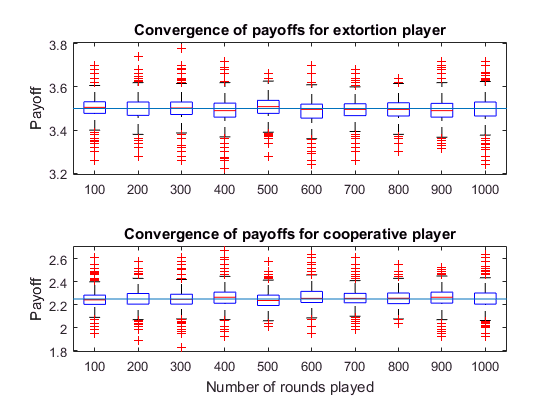

figure
subplot(2,1,1)
boxplot(matPayoffsExtPlayer(:),vecGrouping)
title('Convergence of payoffs for extortion player')
ylabel('Payoff')
hold on
plot([0 NRounds],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
hold off
subplot(2,1,2)
boxplot(matPayoffstmpAllCPlayer(:),vecGrouping)
ylabel('Payoff')
xlabel('Number of rounds played')
title('Convergence of payoffs for cooperative player')
hold on
plot([0 NRounds],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])

From the simulations we see that the standard deviations for both players begin to stabilize after around 1.000 rounds. 

*Standard deviations of payoffs for extortionate and coopoerative players (after 100:1000 numbers of rounds):*

disp([std(matPayoffsExtPlayer);std(matPayoffstmpAllCPlayer)]')

    0.1013    0.1520
    0.0729    0.1093
    0.0586    0.0879
    0.0505    0.0757
    0.0458    0.0687
    0.0425    0.0637
    0.0394    0.0590
    0.0374    0.0560
    0.0358    0.0537
    0.0348    0.0521



However, also 1.000 rounds proved to be too computationally intense for the simulations carried out below. If we look at the distribution of payoffs after 100 simulations, we see that the simulation means for both players falls within around a 12% standard deviation distance of the true value. This is deemed sufficient for the purposes of this analysis and hence the number of games played by any two matched players is set to 100.

*Distance from true payoff value in terms of standard deviations for the extortionate player:*

disp((mean(matPayoffsExtPlayer(:,1)) - (2+chi*13)/(2+chi*3)) / ...
    std(matPayoffsExtPlayer(:,1)))

   -0.1161



*Distance from true payoff value in terms of standard deviations for the cooperative player:*

disp((mean(matPayoffstmpAllCPlayer(:,1)) - (12+3*chi)/(2+3*chi)) ...
    / std(matPayoffstmpAllCPlayer(:,1)))

    0.1161



**Extortion Parameters**

Regarding the impact of the parameters $\Phi$ and $\chi$ we see that $\Phi$ has no influence over the payoffs whereas $\chi$ indeed is proportional to the extortion share of the ZD player. We see faster convergence for lower values of $\chi$ hence I will set it to a relatively modest extortion factor of $\chi =2$ for further runs. We also see that a higher $\phi$ improves convergence. The maximum allowed $\Phi$ for $\chi =2$ is 0.111, hence I will set $\Phi =0\ldotp 1$.

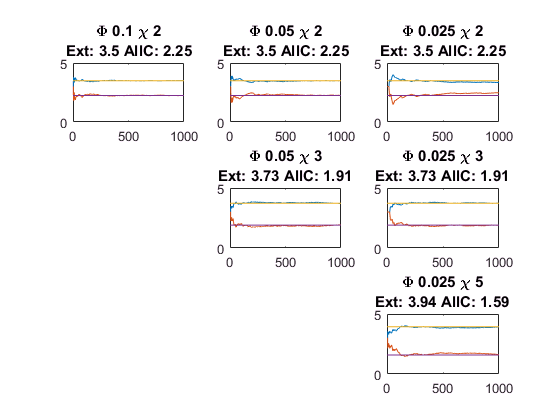

vecPhi = [0.1 0.05 0.025];
vecChi = [2 3 5];

figure 
for i = 1:9
    try
        Phi = vecPhi(mod(i-1,3)+1);
        chi = vecChi(ceil(i/3));
        
        ExtPlayer = PlayerExtortionate(Phi,chi);
        AllCPlayer = AllCPlayer.resetHistory;
        [ExtPlayer,AllCPlayer] = PDGame.playNRounds(1000,ExtPlayer,AllCPlayer);
        
        subplot(3,3,i)
        plot([ExtPlayer.AveragePayoffHistory AllCPlayer.AveragePayoffHistory])
        hold on
        plot([0 1000],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
        plot([0 1000],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])
        ylim([0 5])
        title(['\Phi ' num2str(Phi) ' \chi ' num2str(chi) newline 'Ext: ' ...
            num2str(round(((2+chi*13)/(2+chi*3))*100)/100) ' AllC: ' ...
            num2str(round(((12+3*chi)/(2+3*chi))*100)/100)])
    end
end

## Evolutionary dynamics

Evolutionary dynamics are implemented as follows. A population is initialized with equal shares of two types of players. In every generation, each player is matched with a random opponent (uniform over all other players except for himself) and they play a fixed number of games against each other. Hence in every generation each player will play at least one and on average two games. The scores of all games are kept and averaged over the number of games played in that generation. These payoffs are used to compute the average score per player type (averaged over individuals). The change in shares of player types is governed by standard discrete-time replicator dynamics (see e.g. Bauso 2016). Payoffs are not carried into the next generation and strategies do not evolve.

PopulationSize = 500;
NumberOfGames = 100;
NumberOfGenerations = 5000;

arrOpponents = {'PlayerAllC()' 'PlayerAllD()' ...
    'PlayerTitForTat()' 'PlayerRandom()' 'PlayerPavlov()'};
Games = cell(length(arrOpponents),1);
tic
parfor i = 1:length(arrOpponents)
    strOpponent = arrOpponents{i};
    NewGame = Game([3 0;5 1]);
    NewGame = NewGame.createPopulation(PopulationSize,strOpponent,0.5,...
        'PlayerExtortionate(0.1,2)',0.5);
    NewGame = NewGame.runNGenerationTournament(NumberOfGenerations,NumberOfGames);
    NewGame.plotPopulationHistory(['Extortionate against ' strOpponent(7:end-2) ' player'])
    Games{i} = NewGame;
end
ExecutionTime = toc;

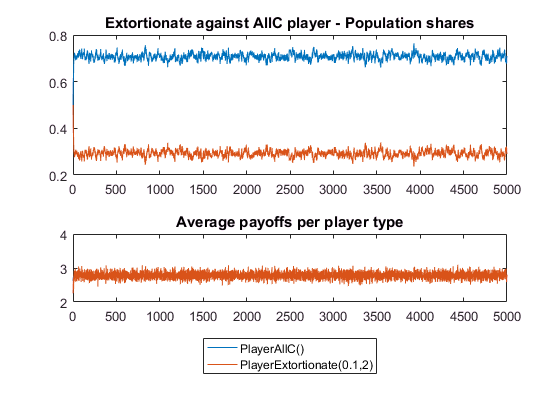

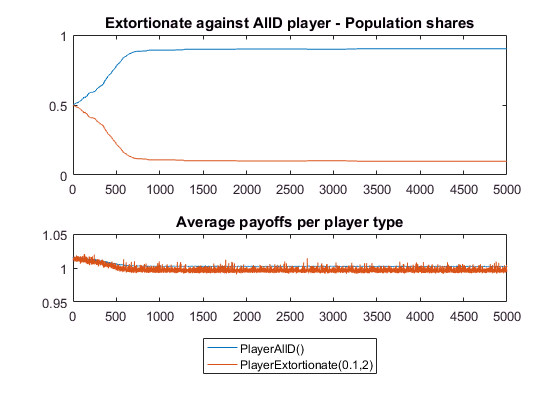

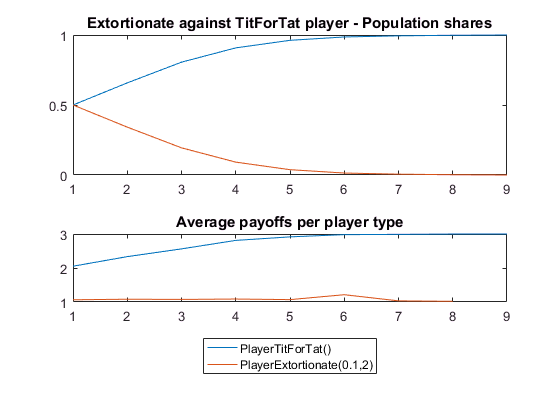

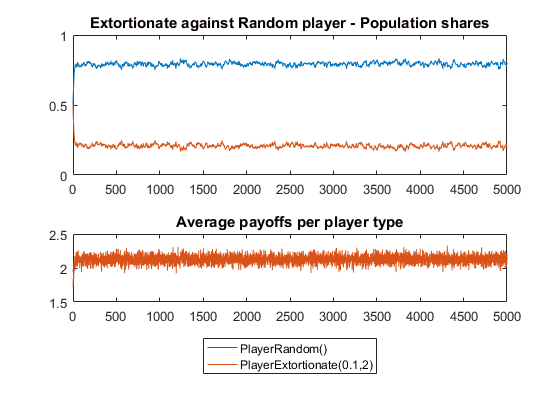

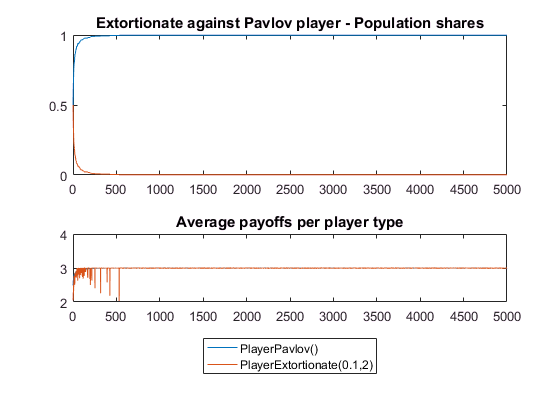

for i = 1:length(arrOpponents)
    tmpGame = Games{i}; strOpponent = arrOpponents{i};
    tmpGame.plotPopulationHistory(['Extortionate against ' strOpponent(7:end-2) ' player'])
end

## Discussion

Adami and Hintze (2013) showed that extortionate ZD strategies are not evolutionarily stable strategies (ESS) in the sense of Smith (1982). Although they perform very well against any other strategy in a 2-player game, they lack a crucial property for ESS. In particular, they do not play well against each other, as their stationary payoff is always equal to the low value P (Adami and Hintze 2013). This means that they may only be able to survive if their share in the population is sufficiently low so that they will mostly be matched against other strategies.

In the simulations above I let an extortionate ZD play against various other strategies, always starting from a population consisting of equal shares of players using one of the two strategies. The strategies against which extortionate ZD was tested were:

- AllC: cooperates unconditionally, characterized by a strategy matrix of propabilities for cooperation $\left(cc,cd,dc,dd\right)=\left(1,1,1,1\right)$

- AllD: $\left(0,0,0,0\right)$: defects unconditionally.

- Tit-for-tat: $\left(1,0,1,0\right)$: starts with a cooperation and always cooperates except for one move following a defection of the opponent.

- Random: $\left(0\ldotp 5,0\ldotp 5,0\ldotp 5,0\ldotp 5\right)$: unconditionally plays a random move.

- Pavlov: $\left(1,0,0,1\right)$: also called "win-stay-lose-shift". Starts with cooperation and sticks to last round's move unless the opponent defects.

The simulation results confirm that extortionate ZD strategies perform poorly against all the tested opponents, the exact behaviour differs by strategy, however. Against AllC, the share of the ZD strategy immediately reaches a dynamic equilibrium where its population share fluctuates around 30% and the average playoffs of both player types reach around 2.8, albeit with a much higher variance for the ZD strategy. This hints at the presence of a sort of "predator-prey-dynamics", where a low share of predatory ZD strategies allows them to meet more often with their AllC-prey, which allows them to temporarily reach a higher population share, until their share grows too large so that they will meet their own kind too often.

AllC = Games{1};
disp([
    mean(AllC.PopulationShareHistory)
    mean(AllC.PlayerTypeAvgPayoffHistory)
    std(AllC.PlayerTypeAvgPayoffHistory) ])

    0.7074    0.2926
    2.7817    2.7827
    0.0185    0.0962



The picture looks different for the AllD-strategy. The share of ZD strategies converges more slowly after around 700 generations to what appears to be a constant share of around 10% (although this would have to be confirmed either analytically or through more extensive simulations). The standard deviation of payoffs is again much higher for the ZD strategy, but interestingly the payoff for the ZD strategy appears to be minimally lower than for the AllD-strategy. It is noteworty that the results against the AllD-strategy are indeed dependent on the strategy for the initial move. If the initial move was set to defect automatically, the population shares would remain constant as all players would always defect, while for a random initial move the picture would look qualitatively similar but with slower convergence.

AllD = Games{2};
disp([
    AllD.PopulationShareHistory([100 500 700 1000:1000:end],:)
    std(AllD.PlayerTypeAvgPayoffHistory(1000:end,:))
    mean(AllD.PlayerTypeAvgPayoffHistory) ])

    0.5380    0.4620
    0.7800    0.2200
    0.8800    0.1200
    0.8920    0.1080
    0.9000    0.1000
    0.8980    0.1020
    0.9020    0.0980
    0.9020    0.0980
    0.0003    0.0029
    1.0034    0.9979



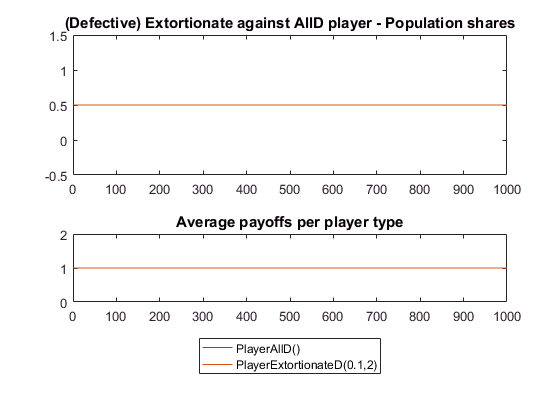

Elapsed time is 208.299209 seconds.


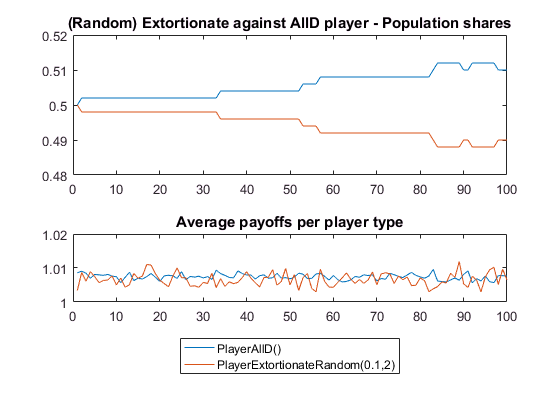

AltGame = Game([3 0;5 1]);

AltGame = AltGame.createPopulation(PopulationSize,'PlayerAllD()',0.5,...
        'PlayerExtortionateD(0.1,2)',0.5);
AltGame = AltGame.runNGenerationTournament(1000,NumberOfGames);
AltGame.plotPopulationHistory(['(Defective) Extortionate against AllD player'])

    0.5000    0.5000
    0.6580    0.3420
    0.8060    0.1940
    0.9080    0.0920
    0.9620    0.0380
    0.9860    0.0140
    0.9940    0.0060
    0.9980    0.0020
    1.0000         0



AltRGame = Game([3 0;5 1]);
AltRGame = AltRGame.createPopulation(PopulationSize,'PlayerAllD()',0.5,...
        'PlayerExtortionateRandom(0.1,2)',0.5);
tic
AltRGame = AltRGame.runNGenerationTournament(100,NumberOfGames);

    0.7918    0.2082
    2.1272    2.1274
    0.0185    0.0962



toc
AltRGame.plotPopulationHistory(['(Random) Extortionate against AllD player'])

The simulation terminated early against the Tit-for-Tat player as the population share of the Tit-for-Tat player reached 100% already in the 9th generation.

TfT = Games{3};

    0.7740    0.2260
    0.9220    0.0780
    0.9640    0.0360
    0.9980    0.0020
    0.9980    0.0020
    0.9980    0.0020
    0.9980    0.0020
    0.9980    0.0020



disp(TfT.PopulationShareHistory(1:9,:))

The picture against the random player is qualitatively similar as against the AllD-player. A dynamic equilibrium with a population share of about 20% for the ZD strategy is quickly reached. The payoffs are again similar for both players but with a higher variance for the ZD player.

Random = Games{4};
disp([
    mean(Random.PopulationShareHistory)
    mean(Random.PlayerTypeAvgPayoffHistory)
    std(AllC.PlayerTypeAvgPayoffHistory) ])

The simulation result against the Pavlov player again shows quick convergence to a population share of the ZD strategy of almost 0%. It would require further investiation to determine whether the continued presence of a minuscule share of ZD players in the population for 4.000 generations is a numerical artefact or a fundamental property of this competition.

Pavlov = Games{5};
disp(Pavlov.PopulationShareHistory([10 50 100 1000:1000:end],:))

## Conclusion & Outlook

This paper used evolutionary simu

Several areas for further investigation were already mentioned in the discussion. Going beyond these questions it would be interesting to test the prediction by Adami and Hintze (2013) that ZD strategies would perform even worse in evolutionary settings with a spatial structure. This setup could also be used to further investigate the result by Hilbe et al (2013) that ZD strategies do indeed perform well in evolutionary settings with distinct populations, e.g. by creating offspring close to the parents but matching them against opponents located far away. One could conjecture that this should lead to pockets of ZD strategies being able to survive. As an additional robustness check, the impact of the use of replicator dynamics versus selection-based algorithms, as discussed by Adami and Hintze (2013) could be investigated.

## References

Adami, C., & Hintze,  A. (2013). Evolutionary instability of zero-determinant strategies  demonstrates that winning is not everything. *Nature communications*, *4:2193*.

Bauso, D. (2016). *Game theory with engineering applications*. Society for Industrial and Applied Mathematics.

Hilbe, C., Nowak, M. A., & Sigmund, K. (2013). Evolution of extortion in iterated prisoner’s dilemma games. *Proceedings of the National Academy of Sciences*, *110*(17), 6913-6918.

Press, W. H., &  Dyson, F. J. (2012). Iterated Prisoner’s Dilemma contains strategies  that dominate any evolutionary opponent. *Proceedings of the National Academy of Sciences*, *109*(26), 10409-10413.

Smith, J. M. (1982). *Evolution and the Theory of Games*. Cambridge university press.

## Annex: UML diagram of implementation